# Agentic AI Workflow Prerequisite Check

This hands-on exercise verifies that the Agentic toolkits are installed before starting the workshop exercises. We will confirm your AI agent can see the MCP tools and run one small MATLAB task.

### Step 1: Use the correct working folder 

Make `Exercise1` your working folder. This is where the prerequisite checks will run.

% Move into the folder for this exercise
scriptFile = matlab.desktop.editor.getActiveFilename;
scriptDir = fileparts(scriptFile);
cd(scriptDir)

### Step 2: Set Up MATLAB or Simulink to Connect to an Agent

To connect your agent to the existing session, run the following command in the MATLAB command window.

**MATLAB users: **

   ` >> shareMATLABSession()`

**Simulink Users: **

   ` >> satk_initialize()`

  Calls shareMATLABSession and sets up the environment to support Simulink workflows

This is already configured for this workshop. 

### Step 3: Open a terminal in MATLAB and start Codex 

% Open a Terminal in MATLAB 
myTerminal = terminal(Theme='dark',StartupCommand='codex');

### Step 4: Check all MCP tools are available to the Agent 

Now we must confirm your agent can see the MCP server and tools needed for this workshop.

We first open our agent (Codex) and then we check our configured MCP server  list. It should include the MATLAB MCP server. 

% Check MCP Server available to use
myTerminal.run("/mcp");
pause(1)
myTerminal.run("");

**Action:**

- Confirm the MATLAB MCP server is connected.

- Confirm 13 MATLAB tools are listed

- 5 MATLAB MCP tools including '`check_matlab_code'`, ' `evaluate_matlab_code'`, and  '`run_matlab_file'` .

- 8 Simulink MCP tools including, including '`model_overview'`, '`model_read'`, '`model_query_params'`, '`model_edit'`, and '`model_check'`.

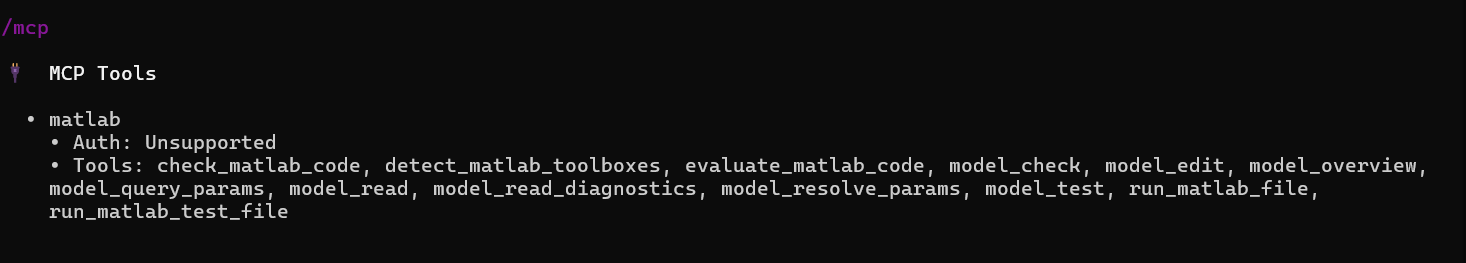

### Step 5: Test  the  MATLAB MCP connection

We will use a MATLAB plotting task to verify that your agent can send code to MATLAB and that MATLAB can return the result.

myTerminal.run("Create and execute a MATLAB function that plots a sine wave in MATLAB " + ...
    "with the title MATLAB Expo Agentic Workshop"); 
pause(1)
myTerminal.run("");